momentofinertia;

s = tf('s');
r2d = 180/pi;
Ixx = ureal('Ixx',Ixx,'Percentage',30);
get(Ixx)

    NominalValue: 0.1379
            Mode: 'Percentage'
           Range: [0.0965 0.1793]
       PlusMinus: [-0.0414 0.0414]
      Percentage: [-30.0000 30.0000]
    AutoSimplify: 'basic'
            Name: 'Ixx'



G = 1/(Ixx*s)*r2d

G =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 3 states.
  The model uncertainty consists of the following blocks:
    Ixx: Uncertain real, nominal = 0.138, variability = [-30,30]%, 1 occurrences

Type "G.NominalValue" to see the nominal value, "get(G)" to see all properties, and "G.Uncertainty" to interact with the uncertain elements.




Kp = 0.1;
Kd = 0.08;
Ki = 0.008;

Kp_ang = 4.5;

PID = K_gain*pid(Kp,Ki,Kd)

PID =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.246, Ki = 0.0197, Kd = 0.197
 
Continuous-time PID controller in parallel form.



P = pid(Kp_ang, 0, 0)

P =
 
  Kp = 4.5
 
P-only controller.




%Motors
max_thrust = 940/1000 * 10;
max_rpm = 13610;
k = max_thrust / (max_rpm^2);
k = ureal('k',k,'Percentage',30);
p2w = max_rpm/1000;
wh = 5444;
l = 0.3;
Td = 20*0.005;
Td = ureal('Td',Td,'Percentage',100);
%delay = exp(-s*Td);
% [n,d] = pade(Td,2);
% delay = tf(n,d)
a = 0.5; b = 1/12;
delay = (1-a*Td*s+b*(Td*s)^2)/(1+a*Td*s+b*(Td*s)^2);
MOT1 = 8*l*k*wh*p2w;
MOTN = (N-1)*8*l*k*wh*p2w*delay;
MOT = MOT1+MOTN;


G0 = MOT*G;
G2 = feedback(PID*MOT*G,1);
G_OL = P*G2*1/s;
G_CL = feedback(P*G2,1/s)*1/s

G_CL =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 21 states.
  The model uncertainty consists of the following blocks:
    Ixx: Uncertain real, nominal = 0.138, variability = [-30,30]%, 1 occurrences
    Td: Uncertain real, nominal = 0.1, variability = [-100,100]%, 6 occurrences
    k: Uncertain real, nominal = 5.07e-08, variability = [-30,30]%, 2 occurrences

Type "G_CL.NominalValue" to see the nominal value, "get(G_CL)" to see all properties, and "G_CL.Uncertainty" to interact with the uncertain elements.



% opt = robOptions('Display','on','Sensitivity','on');
% [StabilityMargin,wcu] = robstab(G_CL,opt);
% wcu

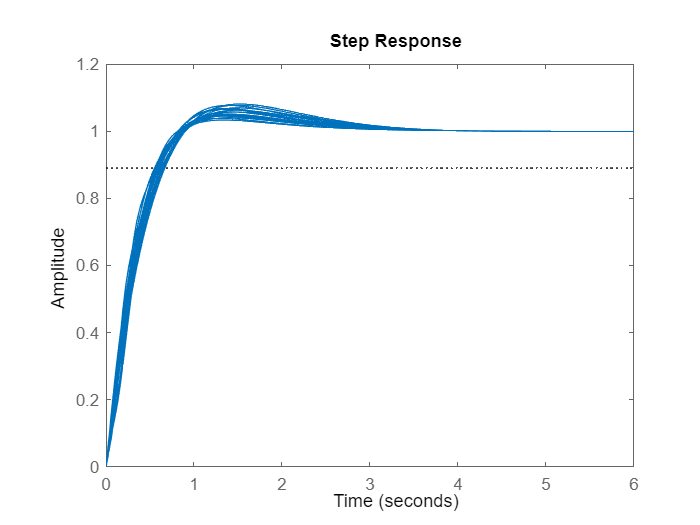

step(G_CL);

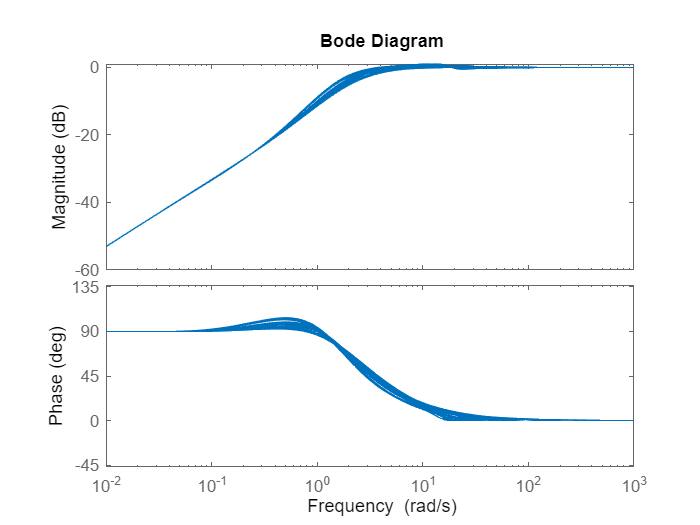

sensitivity = feedback(1,G_OL);
[mag,phase,wout] = bode(sensitivity);
bode(sensitivity)

mag_max = max(mag);
sens_max = 10^(mag_max/20)

sens_max = 1.1301

% disk = diskmargin(G_OL) 
% diskmarginplot(disk.GainMargin)
% sensitivity = feedback(1,G_OL);
% [mag,phase,wout] = bode(sensitivity);
% mag_max = max(mag);
% mu = 10^(mag_max/20)
% figure(1);
% step(G_CL*1/s); hold on;
% figure(2);
% bode(G_OL); hold on;